# Assignment 3: Plotting with Subplots and Tiledlayout in MATLAB

## 1. Generate a dataset of 100 random points for x and y.

% Number of data points
num_points = 100;

% Generate random x and y coordinates
x = rand(num_points, 1); % Random values between 0 and 1
y = rand(num_points, 1); % Random values between 0 and 1

% Display the generated dataset
disp('Generated Dataset:');

Generated Dataset:


dataset = [x, y];
disp(dataset);

    0.2277    0.0835
    0.4357    0.1332
    0.3111    0.1734
    0.9234    0.3909
    0.4302    0.8314
    0.1848    0.8034
    0.9049    0.0605
    0.9797    0.3993
    0.4389    0.5269
    0.1111    0.4168
    0.2581    0.6569
    0.4087    0.6280
    0.5949    0.2920
    0.2622    0.4317
    0.6028    0.0155
    0.7112    0.9841
    0.2217    0.1672
    0.1174    0.1062
    0.2967    0.3724
    0.3188    0.1981
    0.4242    0.4897
    0.5079    0.3395
    0.0855    0.9516
    0.2625    0.9203
    0.8010    0.0527
    0.0292    0.7379
    0.9289    0.2691
    0.7303    0.4228
    0.4886    0.5479
    0.5785    0.9427
    0.2373    0.4177
    0.4588    0.9831
    0.9631    0.3015
    0.5468    0.7011
    0.5211    0.6663
    0.2316    0.5391
    0.4889    0.6981
    0.6241    0.6665
    0.6791    0.1781
    0.3955    0.1280
    0.3674    0.9991
    0.9880    0.1711
    0.0377    0.0326
    0.8852    0.5612
    0.9133    0.8819
    0.7962    0.6692
    0.0987    0.1904
    0.2619   

## 2. Using subplot:

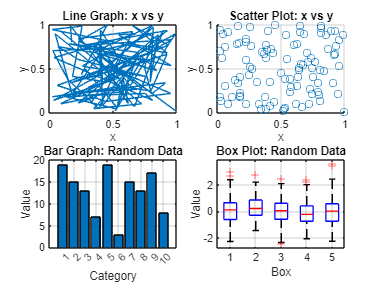

% Generate random data for x and y coordinates
num_points = 100;
x = rand(num_points, 1);
y = rand(num_points, 1);

% Generate random data for bars
num_bars = 10;
bar_data = randi([1, 20], 1, num_bars);

% Generate random data for boxes
num_boxes = 5;
box_data = randn(100, num_boxes);

% Set up a figure with subplots
figure;

% Plot a line graph of x vs y
subplot(2, 2, 1);
plot(x, y);
title('Line Graph: x vs y');
xlabel('x');
ylabel('y');
grid on;

% Plot a scatter plot of x vs y
subplot(2, 2, 2);
scatter(x, y);
title('Scatter Plot: x vs y');
xlabel('x');
ylabel('y');
grid on;

% Plot a bar graph of random data
subplot(2, 2, 3);
bar(bar_data);
title('Bar Graph: Random Data');
xlabel('Category');
ylabel('Value');
grid on;

% Plot a box plot of random data
subplot(2, 2, 4);
boxplot(box_data);
title('Box Plot: Random Data');
xlabel('Box');
ylabel('Value');
grid on;

## 3. Repeat step 2 but using tiledlayout instead of subplot.

% Generate random data for x and y coordinates
num_points = 100;
x = rand(num_points, 1);
y = rand(num_points, 1);

% Generate random data for bars
num_bars = 10;
bar_data = randi([1, 20], 1, num_bars);

% Generate random data for boxes
num_boxes = 5;
box_data = randn(100, num_boxes);

% Create a tiled layout with 2 rows and 2 columns
tiledlayout(2, 2);

% Plot a line graph of x vs y
ax1 = nexttile;
plot(ax1, x, y);
title(ax1, 'Line Graph: x vs y');
xlabel(ax1, 'x');
ylabel(ax1, 'y');
grid(ax1, 'on');

% Plot a scatter plot of x vs y
ax2 = nexttile;
scatter(ax2, x, y);
title(ax2, 'Scatter Plot: x vs y');
xlabel(ax2, 'x');
ylabel(ax2, 'y');
grid(ax2, 'on');

% Plot a bar graph of random data
ax3 = nexttile;
bar(ax3, bar_data);
title(ax3, 'Bar Graph: Random Data');
xlabel(ax3, 'Category');
ylabel(ax3, 'Value');
grid(ax3, 'on');

% Plot a box plot of random data
ax4 = nexttile;
boxplot(ax4, box_data);

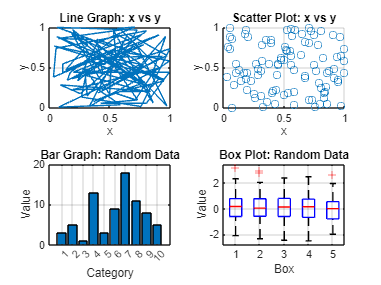

title(ax4, 'Box Plot: Random Data');
xlabel(ax4, 'Box');
ylabel(ax4, 'Value');
grid(ax4, 'on');